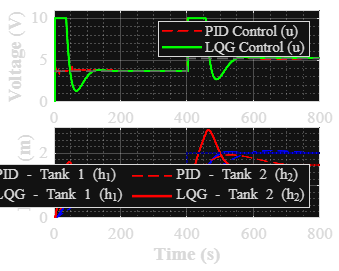


% COMPARACIÓN PID vs LQG - VERSIÓN DE ALTA RESOLUCIÓN Y TAMAÑO MAXIMIZADO

clc; clear; close all;

%  1. CONFIGURACIÓN DE AJUSTE 
ajuste_manual = 0; % Ajuste de tiempo en segundos
buffer_puntos = 100; % Datos previos al escalón para evitar cortes

% 2. PROCESAMIENTO DE DATOS LQG

filename_lqg = 'LQG3.csv'; 
try
    data_lqg = readmatrix(filename_lqg, 'Delimiter', ';', 'DecimalSeparator', ',');
catch
    data_lqg = readmatrix(filename_lqg); 
end

t_raw_lqg  = (data_lqg(:,2) - data_lqg(1,2)) / 1000; 
l1_raw_lqg = data_lqg(:,3); 

% Detectar inicio de subida y aplicar margen
idx_trigger = find(l1_raw_lqg > 0.01, 1, 'first');
if isempty(idx_trigger), idx_trigger = 1; end 
idx_start_lqg = max(1, idx_trigger - buffer_puntos);

% Recortar y normalizar tiempo
t_lqg  = t_raw_lqg(idx_start_lqg:end);
t_lqg  = t_lqg - t_lqg(1) + ajuste_manual;
l1_lqg = data_lqg(idx_start_lqg:end, 3);
l2_lqg = data_lqg(idx_start_lqg:end, 4);
u_lqg  = data_lqg(idx_start_lqg:end, 5);


% 3. PROCESAMIENTO DE DATOS PID

filename_pid = 'PID3.csv'; 
try
    data_pid = readmatrix(filename_pid, 'Delimiter', ';', 'DecimalSeparator', ',');
catch
    data_pid = readmatrix(filename_pid); 
end

t_raw_pid  = (data_pid(:,2) - data_pid(1,2)) / 1000; 
l1_raw_pid = data_pid(:,3); 

% Detectar inicio de subida y aplicar margen
idx_trigger_pid = find(l1_raw_pid > 0.01, 1, 'first');
if isempty(idx_trigger_pid), idx_trigger_pid = 1; end
idx_start_pid = max(1, idx_trigger_pid - buffer_puntos);

% Recortar y normalizar tiempo
t_pid  = t_raw_pid(idx_start_pid:end);
t_pid  = t_pid - t_pid(1) + ajuste_manual;
l1_pid = data_pid(idx_start_pid:end, 3);
l2_pid = data_pid(idx_start_pid:end, 4);
u_pid  = data_pid(idx_start_pid:end, 5);


% 4. REFERENCIAS Y GENERACIÓN DE GRÁFICA

t_cambio = 400; 
t_final  = 800;

t_ref  = [0, t_cambio, t_cambio, t_final];
ref_u  = [3.6834, 3.6834, 5.2091, 5.2091];
ref_h1 = [1.0000, 1.0000, 2.0000, 2.0000];
ref_h2 = [0.8178, 0.8178, 1.6357, 1.6357];

% Configuración de la Figura (Tamaño grande en píxeles)
hFig = figure('Units', 'pixels', 'Position', [100 100 1000 800], 'Color', 'w');

% Tiledlayout elimina los espacios en blanco excesivos entre gráficas
tlo = tiledlayout(2, 1, 'Padding', 'compact', 'TileSpacing', 'tight');

% --- SUBPLOT 1: SEÑAL DE CONTROL (VOLTAJE) ---
nexttile; hold on;
plot(t_pid, u_pid, '--r', 'LineWidth', 1.3, 'DisplayName', 'PID Control (u)');
plot(t_lqg, u_lqg, 'g', 'LineWidth', 1.8, 'DisplayName', 'LQG Control (u)');
plot(t_ref, ref_u, '--', 'Color', [0.4 0.4 0.4], 'LineWidth', 1.2, 'HandleVisibility', 'off');

grid on; grid minor; box on;
ylabel('Voltage (V)', 'FontSize', 14, 'FontWeight', 'bold', 'FontName', 'Times New Roman');
xlim([0 t_final]); ylim([0 11]); 
legend('Location', 'northeast', 'FontSize', 11, 'FontName', 'Times New Roman');
set(gca, 'FontName', 'Times New Roman', 'FontSize', 13);

% SUBPLOT 2: NIVELES DE LOS TANQUES 
nexttile; hold on;
% Tanque 1 (h1)
plot(t_pid, l1_pid, '--b', 'LineWidth', 1.3, 'DisplayName', 'PID - Tank 1 (h_1)');
plot(t_lqg, l1_lqg, '-b', 'LineWidth', 1.8, 'DisplayName', 'LQG - Tank 1 (h_1)');
% Tanque 2 (h2)
plot(t_pid, l2_pid, '--r', 'LineWidth', 1.3, 'DisplayName', 'PID - Tank 2 (h_2)');
plot(t_lqg, l2_lqg, '-r', 'LineWidth', 1.8, 'DisplayName', 'LQG - Tank 2 (h_2)');

% Dibujar líneas de referencia (punteadas)
plot(t_ref, ref_h1, ':', 'Color', [0 0 0.5], 'LineWidth', 1.5, 'HandleVisibility', 'off'); 
plot(t_ref, ref_h2, ':', 'Color', [0.5 0 0], 'LineWidth', 1.5, 'HandleVisibility', 'off');

grid on; grid minor; box on;
ylabel('Level (m)', 'FontSize', 14, 'FontWeight', 'bold', 'FontName', 'Times New Roman');
xlabel('Time (s)', 'FontSize', 14, 'FontWeight', 'bold', 'FontName', 'Times New Roman');
xlim([0 t_final]); ylim([0 2.8]); 

legend('Location', 'southeast', 'FontSize', 11, 'FontName', 'Times New Roman', 'NumColumns', 2);
set(gca, 'FontName', 'Times New Roman', 'FontSize', 13);



% 5. CÁLCULO DE ÍNDICES DE DESEMPEÑO (L1)


% Vector de referencia dinámico para el cálculo (ajustado a los tiempos de cada sensor)
ref_l1_lqg = (t_lqg >= t_cambio)*2.0 + (t_lqg < t_cambio)*1.0;
ref_l1_pid = (t_pid >= t_cambio)*2.0 + (t_pid < t_cambio)*1.0;

% CÁLCULO PARA LQG
dt_lqg = mean(diff(t_lqg));
error_lqg = abs(ref_l1_lqg - l1_lqg);
IAE_lqg = sum(error_lqg) * dt_lqg;
ITAE_lqg = sum(t_lqg .* error_lqg) * dt_lqg;

%  CÁLCULO PARA PID 
dt_pid = mean(diff(t_pid));
error_pid = abs(ref_l1_pid - l1_pid);
IAE_pid = sum(error_pid) * dt_pid;
ITAE_pid = sum(t_pid .* error_pid) * dt_pid;

% Mostrar resultados en consola
fprintf('\n--- RESULTADOS DE DESEMPEÑO L1 ---\n');


--- RESULTADOS DE DESEMPEÑO L1 ---


fprintf('LQG -> IAE: %.2f | ITAE: %.2f\n', IAE_lqg, ITAE_lqg);

LQG -> IAE: 96.43 | ITAE: 25858.61


fprintf('PID -> IAE: %.2f | ITAE: %.2f\n', IAE_pid, ITAE_pid);

PID -> IAE: 201.02 | ITAE: 55545.02
